# Testing

## Testing di Robustezza

### Testing sul numero di input

load mathwork200.mat;
[R, OUT, IN] = PageRank();

Error using PageRank (line 5)
Inserire come parametro di input la matrice G

### Testing sul numero di output

load mathwork200.mat;
R = PageRank(G);

Error using PageRank (line 8)
Inserire come parametri di output R, OUT, IN

### Testing sulla matrice G

#### Testo se è una matrice

G=rand(10,10,10);
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 12)
Il primo input deve essere una matrice.

#### Testo se è sparsa o vuota

G=rand(100,100);
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 14)
La matrice deve essere sparsa e non vuota.

G=[];
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 14)
La matrice deve essere sparsa e non vuota.

#### Testo se è quadrata

G=sparse(rand(100,50));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 16)
La matrice deve essere quadrata.

#### Testo se è composta da elementi logical

G=sparse(rand(100,100));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 18)
Gli elementi della matrice devono essere logici.

## Testing di Funzionamento

load mathwork200.mat;
[R, OUT, IN] = PageRank(G)

R =    0.001759217077077
   0.005536967249761
   0.004787988545060
   0.004798261903168
   0.004798261903168
   0.004787988545060
   0.004787988545060
   0.004787988545060
   0.004787988545060
   0.004787988545060


OUT =     20
    19
    19
    20
    20
    19
    19
    19
    19
    19


IN =      0
    18
    16
    16
    16
    16
    16
    16
    16
    16


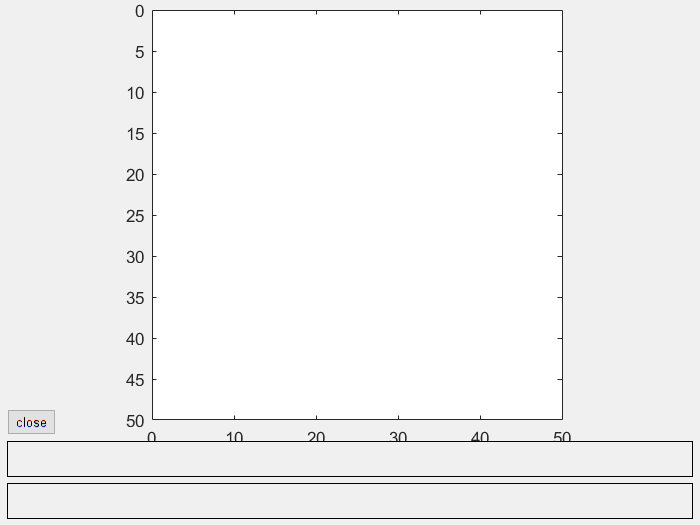

[U,G]=surfer('http://www.unina.it',50);

[R, OUT, IN] = PageRank(G)

R =    0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000
   0.020000000000000


OUT =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


IN =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Testing di Accuratezza

load repubblica.mat;
H=digraph(G');
[R, OUT, IN] = PageRank(G);
pg_ranks=centrality(H,'pagerank','MaxIterations',200,'FollowProbability',0.85,'Tolerance',10^-7);
err=norm(R-pg_ranks)/norm(pg_ranks)

err =      3.187280483920667e-06
